This file calculates the resolution of the elevation axis. Accelerometer datasheet found [here](https://files.seeedstudio.com/products/114020121/document/lis3dh.pdf).

% Setup
clc
clear all

% Constants
earth_g = 9.81;
sensitivity = 1e-3;  % g/bit - From datasheet when accelerometer is in high resolution mode
sensitivity = sensitivity * earth_g;  % (m/s2)/bit

Approach:

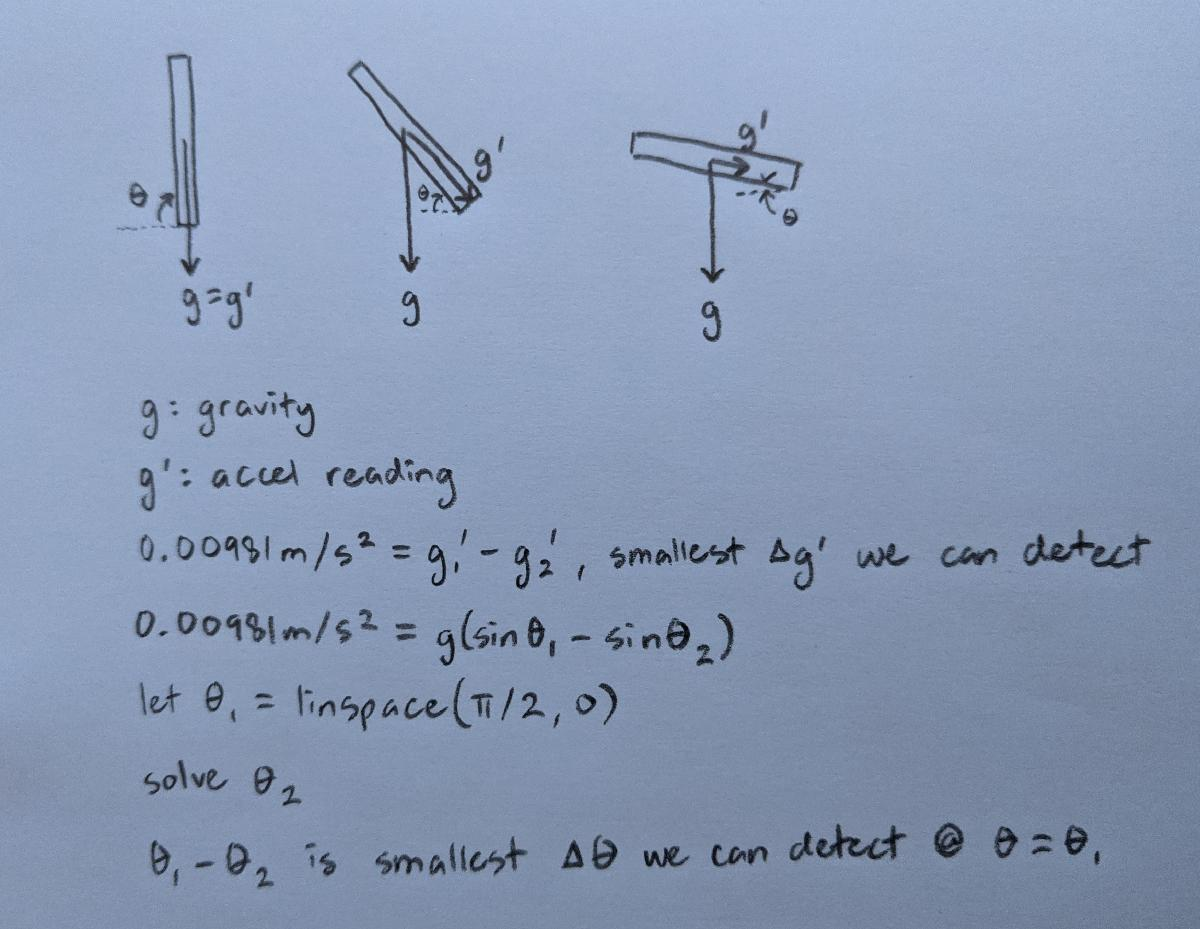

Calculate the resolution in degrees/bit at varying elevation angles

N = 90;
theta_1 = linspace(pi/2, 0, N);
soln = zeros(1, N);
syms x
for i = 1:N
    eqn = sin(theta_1(i)) - sin(x) == 1e-3;
    solution = solve(eqn,x);
    soln(i) = solution(1);
end

Plot the results.

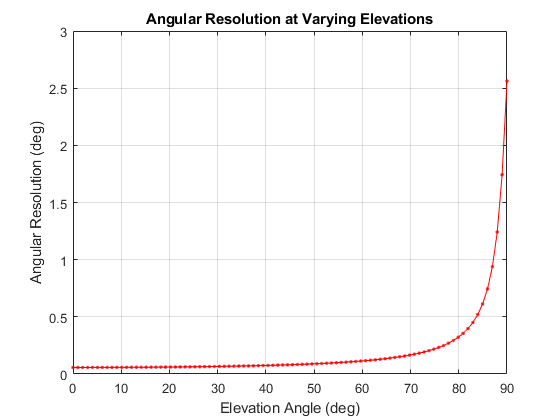

deg_change_per_bit = rad2deg(theta_1 - soln);
clf
figure(1)
plot(rad2deg(theta_1), deg_change_per_bit, 'r.-')
grid on;
xlabel('Elevation Angle (deg)');
ylabel('Angular Resolution (deg)');
title('Angular Resolution at Varying Elevations')